Function

f=@(x) (1 - exp(-x))

f = function_handle with value:
    @(x)(1-exp(-x))


xx = linspace(0,4)

xx =                          0        0.0404040404040404        0.0808080808080808         0.121212121212121         0.161616161616162         0.202020202020202         0.242424242424242         0.282828282828283         0.323232323232323         0.363636363636364         0.404040404040404         0.444444444444444         0.484848484848485         0.525252525252525         0.565656565656566         0.606060606060606         0.646464646464647         0.686868686868687         0.727272727272727         0.767676767676768         0.808080808080808         0.848484848484849         0.888888888888889         0.929292929292929          0.96969696969697          1.01010101010101          1.05050505050505          1.09090909090909          1.13131313131313          1.17171717171717          1.21212121212121          1.25252525252525          1.29292929292929          1.33333333333333          1.37373737373737          1.41414141414141          1.45454545454545           1.4949494949495       

yy = f(xx)

yy =                          0        0.0395986801876422        0.0776293049026812         0.114153967072293         0.149232300825689         0.182921578859269         0.215276805946244         0.246350808743404         0.276194322041649         0.304856071601121          0.33238285370617         0.358819611570045         0.384209508714071         0.408593999441094         0.432012896518279         0.454504436179757         0.476105340555252         0.496850877626618         0.516774918810175         0.535909994258858         0.554287345974482         0.571936978816824         0.588887709492813         0.605167213605816         0.620802070841835         0.635817808366385         0.650238942502919         0.664089018760838         0.677390650278444         0.690165554743611         0.702434589852435         0.714217787363773         0.725534385805271         0.736402861884273         0.746840960654896         0.756865724490533         0.766493520909087          0.77574006929635       

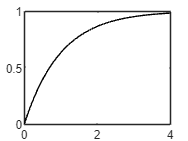

plot(xx,yy,'k-')

To integrate function from 0 to 0.8

a = 0

a =      0


b = 4

b =      4


p =[2 0 -4 0 -1 1]

p =      2     0    -4     0    -1     1


q = polyint(p)

q =          0.333333333333333                         0                        -1                         0                      -0.5                         1                         0


%Itrue = diff(polyval(q,[a,b]))
Itrue = 3.018316

Itrue =                   3.018316


Plot original function along with trapezoidal rule ns = 1

ns = 1

ns =      1


x = linspace(a,b,ns+1)

x =      0     4


y = f(x)

y =                          0         0.981684361111266


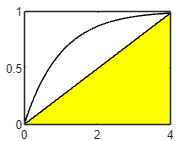


figure
area(x,y,'FaceColor','y','EdgeColor','black','LineStyle','-')
hold on
plot(xx,yy,'k-')

I_trap_1 = trap(f,a,b,1)

I_trap_1 =           1.96336872222253



err = abs(Itrue - I_trap_1)/Itrue

err =          0.349515185877645


err = err * 100

err =           34.9515185877645


Plot original function along with trapezoidal rule ns = 2

ns = 2

ns =      2


x = linspace(a,b,ns+1)

x =      0     2     4


y = f(x)

y =                          0         0.864664716763387         0.981684361111266



figure 
color=['g','y']

color = 'gy'

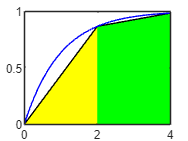

for i = 1:ns
    area(x(i:i+1),y(i:i+1),'FaceColor',color(mod(i,2)+1),'EdgeColor','black','LineStyle','-')    
    hold on
end
plot(xx,yy,'b-')

I_trap_2 = trap(f,a,b,2)

I_trap_2 =           2.71101379463804


err = abs(Itrue - I_trap_2)/Itrue

err =          0.101812469390866


err = err * 100

err =           10.1812469390866


Plot original function along with trapezoidal rule ns = 3

ns = 3

ns =      3


x = linspace(a,b,ns+1)

x =                          0          1.33333333333333          2.66666666666667                         4


y = f(x)

y =                          0         0.736402861884273         0.930516548777198         0.981684361111266



figure 
color=['g','y']

color = 'gy'

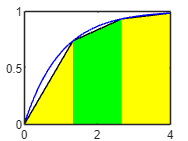

for i = 1:ns
    area(x(i:i+1),y(i:i+1),'FaceColor',color(mod(i,2)+1),'EdgeColor','black','LineStyle','-')    
    hold on
end
plot(xx,yy,'b-')

ns = 4

ns =      4


x = linspace(a,b,ns+1)

x =      0     1     2     3     4


y = f(x)

y =                          0         0.632120558828558         0.864664716763387         0.950212931632136         0.981684361111266



figure 
color=['g','y']

color = 'gy'

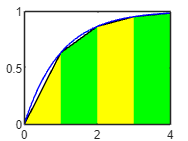

for i = 1:ns
    area(x(i:i+1),y(i:i+1),'FaceColor',color(mod(i,2)+1),'EdgeColor','black','LineStyle','-')    
    hold on
end
plot(xx,yy,'b-')

I_trap_4 = trap(f,a,b,4)

I_trap_4 =           2.93784038777971


err = abs(Itrue - I_trap_4)/Itrue

err =         0.0266624211051084


err = err * 100

err =           2.66624211051084


Plot original function along with trapezoidal rule ns from 1 until 10

Plot original function along with trapezoidal rule ns = 3

ns =      5


x =                          0                       0.8                       1.6                       2.4                       3.2                         4


y =                          0         0.550671035882778         0.798103482005345         0.909282046710588         0.959237796021634         0.981684361111266


color = 'gy'

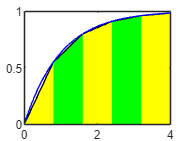

ns =      6


x =                          0         0.666666666666667          1.33333333333333                         2          2.66666666666667          3.33333333333333                         4


y =                          0         0.486582880967408         0.736402861884273         0.864664716763387         0.930516548777198         0.964326006652748         0.981684361111266


color = 'gy'

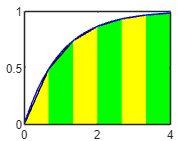

ns =      7


x =                          0         0.571428571428571          1.14285714285714          1.71428571428571          2.28571428571429          2.85714285714286          3.42857142857143                         4


y =                          0         0.435281877992241          0.68109344267603         0.819907687852048         0.898298607695773         0.942567380732383         0.967566759105205         0.981684361111266


color = 'gy'

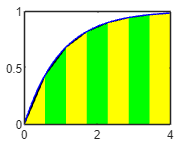

ns =      8


x =                          0                       0.5                         1                       1.5                         2                       2.5                         3                       3.5                         4


y =                          0         0.393469340287367         0.632120558828558          0.77686983985157         0.864664716763387         0.917915001376101         0.950212931632136         0.969802616577682         0.981684361111266


color = 'gy'

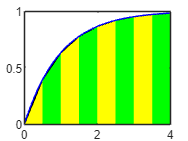

ns =      9


x =                          0         0.444444444444444         0.888888888888889          1.33333333333333          1.77777777777778          2.22222222222222          2.66666666666667          3.11111111111111          3.55555555555556                         4


y =                          0         0.358819611570045         0.588887709492813         0.736402861884273         0.830986684593934         0.891631976778104         0.930516548777198          0.95544857375551          0.97143449921545         0.981684361111266


color = 'gy'

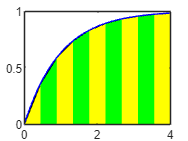

ns =     10


x =                          0                       0.4                       0.8                       1.2                       1.6                         2                       2.4                       2.8                       3.2                       3.6                         4


y =                          0         0.329679953964361         0.550671035882778         0.698805788087798         0.798103482005345         0.864664716763387         0.909282046710588         0.939189937374782         0.959237796021634         0.972676277552707         0.981684361111266


color = 'gy'

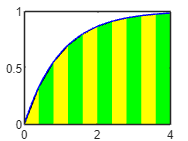

ns =     11


x =                          0         0.363636363636364         0.727272727272727          1.09090909090909          1.45454545454545          1.81818181818182          2.18181818181818          2.54545454545455          2.90909090909091          3.27272727272727          3.63636363636364                         4


y =                          0         0.304856071601121         0.516774918810175         0.664089018760838         0.766493520909087         0.837679388818152         0.887163812682943         0.921562609482869         0.945474724222565         0.962097085599042         0.973652019185551         0.981684361111266


color = 'gy'

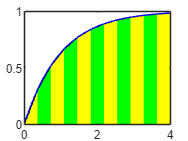

ns =     12


x =                          0         0.333333333333333         0.666666666666667                         1          1.33333333333333          1.66666666666667                         2          2.33333333333333          2.66666666666667                         3          3.33333333333333          3.66666666666667                         4


y =                          0         0.283468689426211         0.486582880967408         0.632120558828558         0.736402861884273         0.811124397162438         0.864664716763387         0.903028032135595         0.930516548777198         0.950212931632136         0.964326006652748         0.974438466793493         0.981684361111266


color = 'gy'

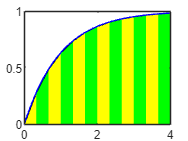

ns =     13


x =                          0         0.307692307692308         0.615384615384615         0.923076923076923          1.23076923076923          1.53846153846154          1.84615384615385          2.15384615384615          2.46153846153846          2.76923076923077          3.07692307692308          3.38461538461538          3.69230769230769                         4


y =                          0         0.264858519408316         0.459567003513466         0.602705286802289         0.707932176308586         0.785288827658303         0.842156910865148          0.88396299775224         0.914696386364161         0.937289775171928         0.953899112471654         0.966109325285821         0.975085559212367         0.981684361111266


color = 'gy'

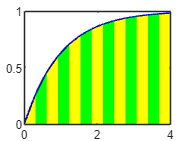

ns =     14


x =                          0         0.285714285714286         0.571428571428571         0.857142857142857          1.14285714285714          1.42857142857143          1.71428571428571                         2          2.28571428571429          2.57142857142857          2.85714285714286          3.14285714285714          3.42857142857143          3.71428571428571                         4


y =                          0         0.248522706924714         0.435281877992241          0.57562715432305          0.68109344267603         0.760348963558224         0.819907687852048         0.864664716763387         0.898298607695773         0.923573713009232         0.942567380732383         0.956840690738547         0.967566759105205          0.97562715592672         0.981684361111266


color = 'gy'

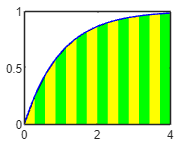

for i = 1:10
    ns = ns+1
    x = linspace(a,b,ns+1)
    y = f(x)

    figure 
    color=['g','y']
    for i = 1:ns
        area(x(i:i+1),y(i:i+1),'FaceColor',color(mod(i,2)+1),'EdgeColor','black','LineStyle','-')
        hold on
    end
    plot(xx,yy,'b-')
end